## Notebook Author

**Hammad Ali**

## Affine transformation for Singular Matrix

Perform affine transformation on grid of points with 1 shear in x direction and 0 shear in y direction.

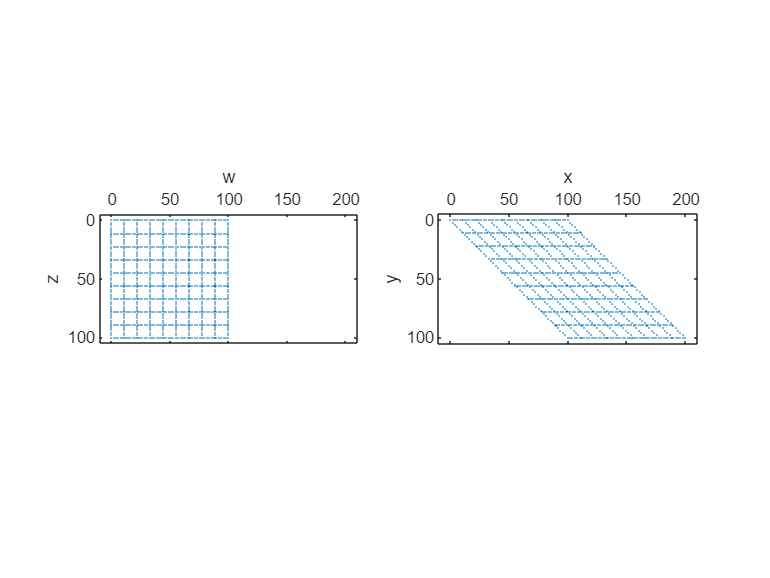

tform = maketform("affine", [1 1 0; 1 0 0; 0 0 1]);
figure, vistform(tform, pointgrid([0 0; 100 100]))

Perform affine transformation on grid of points with 1 shear in x direction and 0.5 shear in y direction.

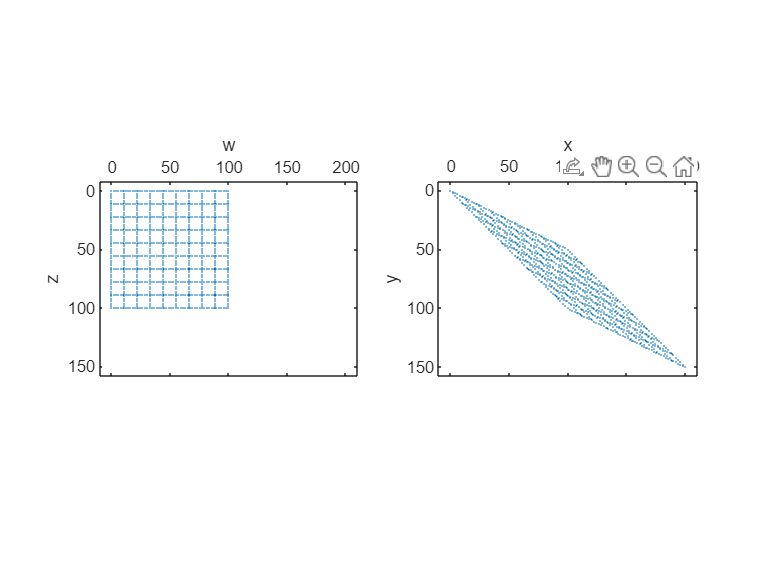

tform1 = maketform("affine", [1 1 0; 1 0.5 0; 0 0 1]);
figure, vistform(tform1, pointgrid([0 0; 100 100]))

Now increase y shear to 0.7

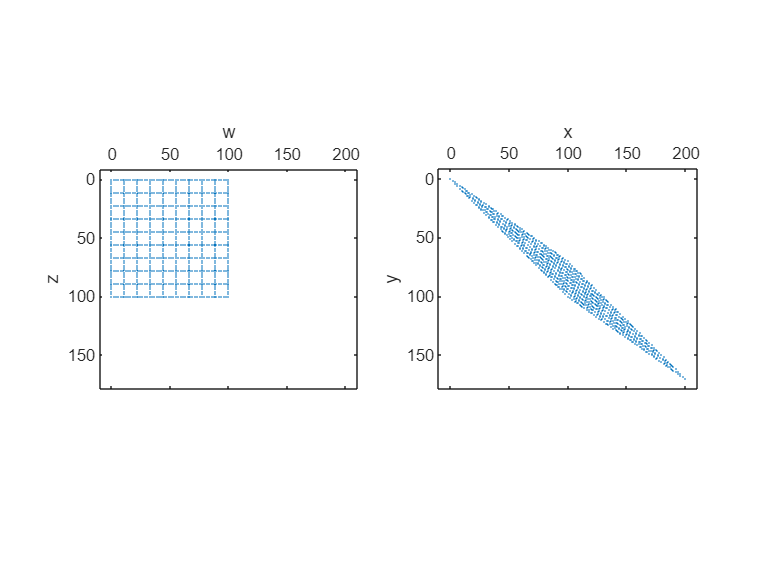

tform1 = maketform("affine", [1 1 0; 1 0.7 0; 0 0 1]);
figure, vistform(tform1, pointgrid([0 0; 100 100]))

As we increase y shear the output grid starts to become like a straight line. Obviously on y shear of 1, it will exactly be a straight line.

tform1 = maketform("affine", [1 1 0; 1 1 0; 0 0 1]);

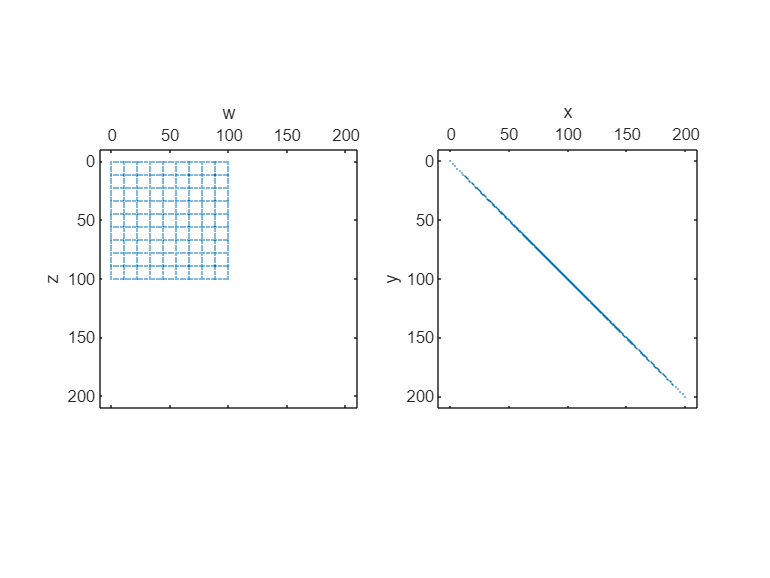

figure, vistform(tform1, pointgrid([0 0; 100 100]))

This happened because the rank of transformation matrix became less than 3 *(due to singularity of matrix)*. Therfore the dimension of output image reduced from 2 to 1. As you further decrease the matrix rank, the resultant image will be just a single point with no dimension.

## Comparison between log and inverse of log

Plotting log and inverse of log on the same graph. We plot the graphs between the range 0 to 1 to see if we get the same curves as discussed in class.

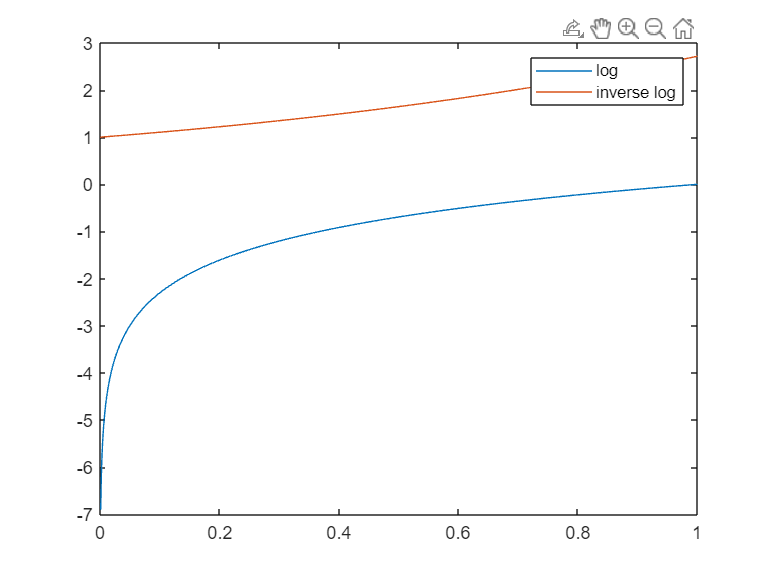

x = linspace(0,1,1000);
y_log = log(x);
y_inv_log = exp(1).^x;
log_plot = plot(x,y_log);
hold on
inv_log_plot = plot(x, y_inv_log);
legend([log_plot inv_log_plot], ["log" "inverse log"])
hold off

From the above plot we see that inverse of log is still greater than log even in the range 0 to 1. Lets try plotting the curve on a different range. This time from 0 to 20.

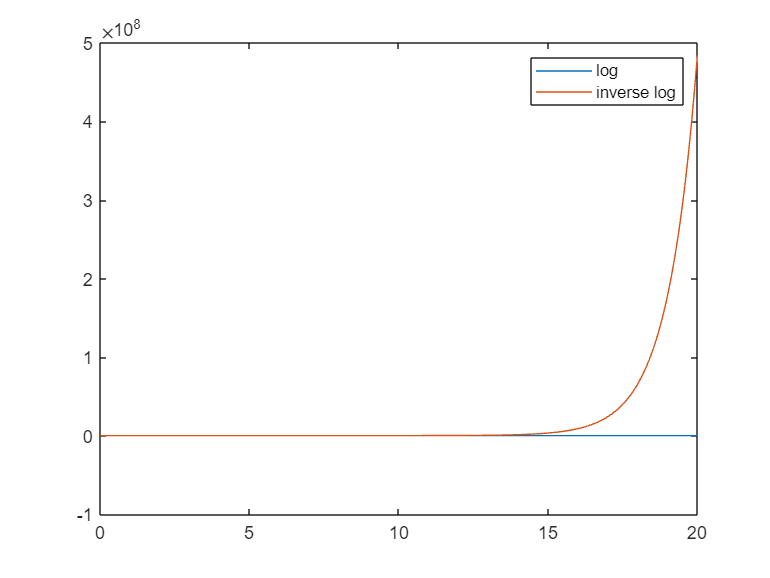

x = linspace(0,20,1000);
y_log = log(x);
y_inv_log = exp(1).^x;
log_plot = plot(x,y_log);
hold on
inv_log_plot = plot(x, y_inv_log);
legend([log_plot inv_log_plot], ["log" "inverse log"])
hold off

Still log function is much smaller than the inverse log. Now lets plot both on different axes.

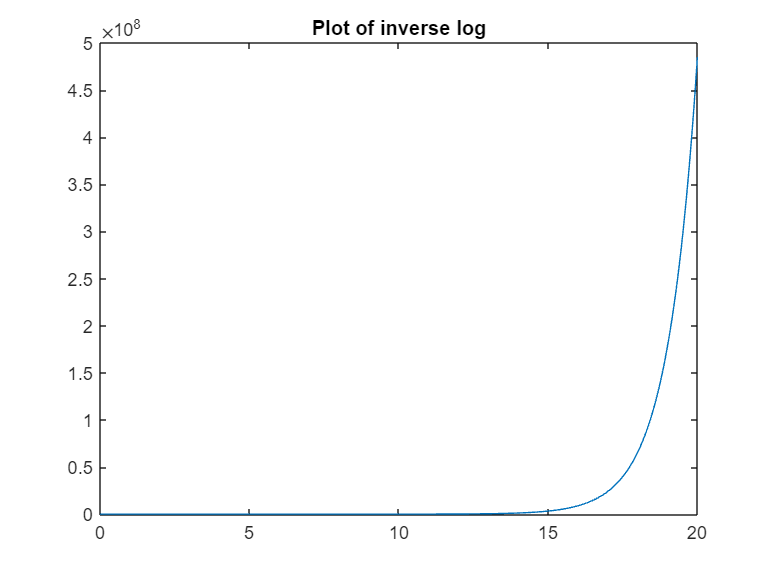

plot(x, y_inv_log);
title("Plot of inverse log");

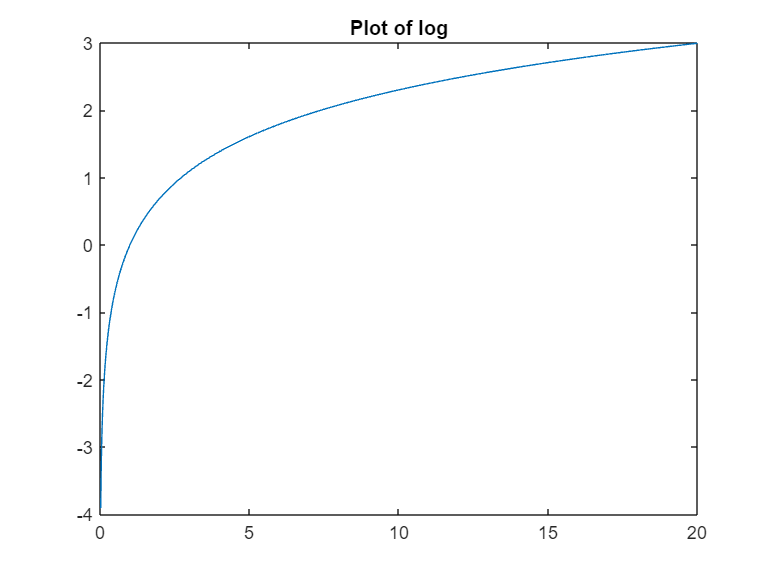

plot(x, y_log)
title("Plot of log")

Although inverse of log is much greater than simple log. Plotting both of these functions in different scales gives similar output as we observed in the class. 

## Conclusion

The figure in book was "scaled independently so that all curves would fit in the same graph. Out interest here is on the shapes of the curves, not on their relative values." *(Digital Image Processing, Edition 4th, Fig 3.3, page# 123)*